## Estimation of the value of the number pi using the Monte Carlo method with visualization.

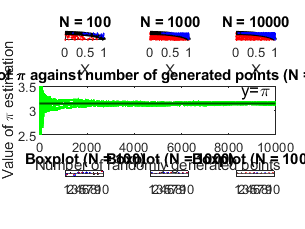

tic
close all; clc; clear;

M = 99;
t = 0:1/M:1;
ft = @(t) sqrt(1-t.^2);
mt = RandStream("twister","Seed",2^32-1);
s = RandStream("twister","Seed",sum(100*clock));

f1 = figure;
for N=[100,1000,10000]
    pi_vector_mt = zeros(1, N);
    val_pi_mt = zeros(1,10);
    box_matrix_mt = zeros(N,10);
    
    for i=1:10
        random_numbers_mt = rand(mt,[2,N]);
        p_w = ft(random_numbers_mt(1,:)) > random_numbers_mt(2,:);
        p_w_cumsum = cumsum(p_w); % Ilosc w okregu.
        pi_vector_mt = (4 * p_w_cumsum) ./ (1:N);
        box_matrix_mt(:,i) = pi_vector_mt(1,:)';
        val_pi_mt(i) = pi_vector_mt(end);
        
        if i == 1 && N == 100
            subplot(3,3,1), scatter(random_numbers_mt(1,p_w), random_numbers_mt(2,p_w), 1.8, "red", "filled");
            hold on
            plot(t, ft(t), "k", "lineWidth", 2.5);
            hold on
            scatter(random_numbers_mt(1,~p_w), random_numbers_mt(2,~p_w), 1.8, "blue", "filled");
            title("N = 100"); xlabel("X"); ylabel("Y");
        elseif i == 1 && N == 1000
            subplot(3,3,2), scatter(random_numbers_mt(1,p_w), random_numbers_mt(2,p_w), 1.8, "red", "filled");
            hold on
            plot(t, ft(t), "k", "lineWidth", 2.5);
            hold on
            scatter(random_numbers_mt(1,~p_w), random_numbers_mt(2,~p_w), 1.8, "blue", "filled");
            title("N = 1000"); xlabel("X"); ylabel("Y");
        elseif i == 1 && N == 10000
            subplot(3,3,3), scatter(random_numbers_mt(1,p_w), random_numbers_mt(2,p_w), 1.8, "red", "filled");
            hold on
            plot(t, ft(t), "k", "lineWidth", 2.5);
            hold on
            scatter(random_numbers_mt(1,~p_w), random_numbers_mt(2,~p_w), 1.8, "blue", "filled");
            title("N = 10000"); xlabel("X"); ylabel("Y");
        end
        
        if i == 10 && N == 100
            subplot(3,3,7),boxplot(box_matrix_mt,'symbol', ''); yline(pi); ylim([2,4]);xtickangle(0);title("Boxplot (N = 100)");
        elseif i == 10 && N == 1000
            subplot(3,3,8),boxplot(box_matrix_mt,'symbol', ''); yline(pi); ylim([2,4]);xtickangle(0);title("Boxplot (N = 1000)");
        elseif i == 10 && N == 10000
            subplot(3,3,9),boxplot(box_matrix_mt,'symbol', ''); yline(pi); ylim([2,4]);xtickangle(0);title("Boxplot (N = 1000)");
        end

        if N==10000
            subplot(3,3,[4,6]), plot(1:N, pi_vector_mt,"g", "LineWidth", 2);             
            hold on
        end
    end
end
ylim([2.5,3.5]); yline(pi,"k",'y=\pi',"LineWidth",1.2); xlabel("Number of randomly generated points"); ylabel("Value of \pi estimation");
title("Value of \pi against number of generated points (N = 10000)");

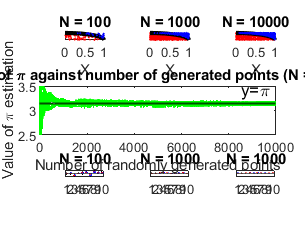


f2 = figure;
for N=[100,1000,10000]
    pi_vector_s = zeros(1, N);
    val_pi_s = zeros(1,10);
    box_matrix_s = zeros(N,10);

    for i=1:10
        random_numbers_s = rand(s,[2,N]);
        p_w = ft(random_numbers_s(1,:)) > random_numbers_s(2,:);
        p_w_cumsum = cumsum(p_w); % Ilosc w okregu.
        pi_vector_s = (4 * p_w_cumsum) ./ (1:N);
        box_matrix_s(:,i) = pi_vector_s(1,:)';
        val_pi_s(i) = pi_vector_s(end);
        
        if i == 1 && N == 100
            subplot(3,3,1), scatter(random_numbers_s(1,p_w), random_numbers_s(2,p_w), 1.8, "red", "filled");
            hold on
            plot(t, ft(t), "k", "lineWidth", 2.5);
            hold on
            scatter(random_numbers_s(1,~p_w), random_numbers_s(2,~p_w), 1.8, "blue", "filled");
            title("N = 100"); xlabel("X"); ylabel("Y");
        elseif i == 1 && N == 1000
            subplot(3,3,2), scatter(random_numbers_s(1,p_w), random_numbers_s(2,p_w), 1.8, "red", "filled");
            hold on
            plot(t, ft(t), "k", "lineWidth", 2.5);
            hold on
            scatter(random_numbers_s(1,~p_w), random_numbers_s(2,~p_w), 1.8, "blue", "filled");
            title("N = 1000"); xlabel("X"); ylabel("Y");
        elseif i == 1 && N == 10000
            subplot(3,3,3), scatter(random_numbers_s(1,p_w), random_numbers_s(2,p_w), 1.8, "red", "filled");
            hold on
            plot(t, ft(t), "k", "lineWidth", 2.5);
            hold on
            scatter(random_numbers_s(1,~p_w), random_numbers_s(2,~p_w), 1.8, "blue", "filled");
            title("N = 10000"); xlabel("X"); ylabel("Y");
        end
        
        if i == 10 && N == 100
            subplot(3,3,7),boxplot(box_matrix_s,'symbol', ''); yline(pi); ylim([2,4]);xtickangle(0);title("N = 100");
        elseif i == 10 && N == 1000
            subplot(3,3,8),boxplot(box_matrix_s,'symbol', ''); yline(pi); ylim([2,4]);xtickangle(0);title("N = 1000");
        elseif i == 10 && N == 10000
            subplot(3,3,9),boxplot(box_matrix_s,'symbol', ''); yline(pi); ylim([2,4]);xtickangle(0);title("N = 1000");
        end

        if N==10000
            subplot(3,3,[4,6]), plot(1:N, pi_vector_s,"g", "LineWidth", 2);             
            hold on
        end
    end
end
ylim([2.5,3.5]); yline(pi,"k",'y=\pi',"LineWidth",1.2); xlabel("Number of randomly generated points"); ylabel("Value of \pi estimation");
title("Value of \pi against number of generated points (N = 10000)");

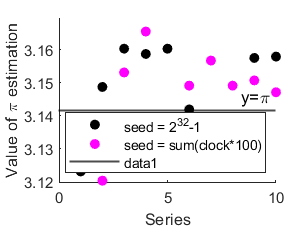


f3 = figure;
scatter(1:10,val_pi_mt,"black","filled"); 
hold on
scatter(1:10,val_pi_s,"m","filled");
legend("seed = 2^{32}-1", "seed = sum(clock*100)","Location","southeast");
yline(pi,"k",'y=\pi',"LineWidth",1.2); xlabel("Series"); ylabel("Value of \pi estimation");

toc

Elapsed time is 3.624504 seconds.
